# ______________Computational Electromagnetics 

## _______________________________ Hw6-Q2

______________________Mohammadreza Arani         :::::::::::::         810100511

 __________________________________________1401/09/28     

clear; clc; close all;

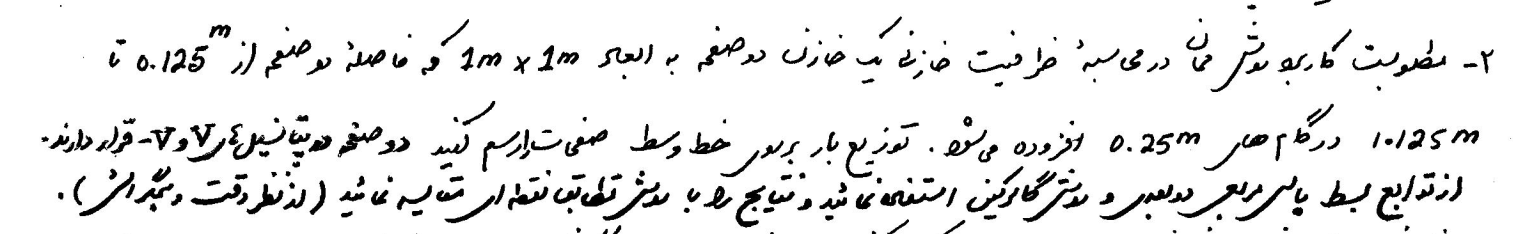

% Prepare for a huge integral calculation......
a = 1; % 1m *  1m surface
       

% L shall be Symmetric:  <Actually a TOEPLITZ Matrix formation will apear>
% disp(Lmn)
N = 9;
d = 0.125;

Lmn_tt =  lmn_tt( a, N );
Lmn_tb =  lmn_tb(a ,  N , d);


% Now find the Alpha Values:
b        = a/sqrt(N);
delta_Sn = (2*b)^2 ;
V =1;

% Alpha_t = inv(  Lmn_tt - Lmn_tb  ) * V;
% C = 1/(2*V) * sum(Alpha_t,'all')*delta_Sn;



eps0 = 8.854*1e-12  ;  % F/m
D       = 0.125: 0.25 : 1.125 ; 
Sweep_N = [ 9 , 16 , 25 , 36 , 49 , 64  , 81 , 100];

C       = zeros( length(D) , length(Sweep_N));
C_plate = zeros( length(D),1);

A  = (2*a)^2;

Alpha_t =cell(1,length(D)) ;

for i=1:length(D)
    for j=1:length(Sweep_N)
        
        [C(i,j) , Alpha_t{i}] = Find_C(D(i) , Sweep_N(j),a );

    end
    C_plate(i,1) =  eps0*A/D(i);

end

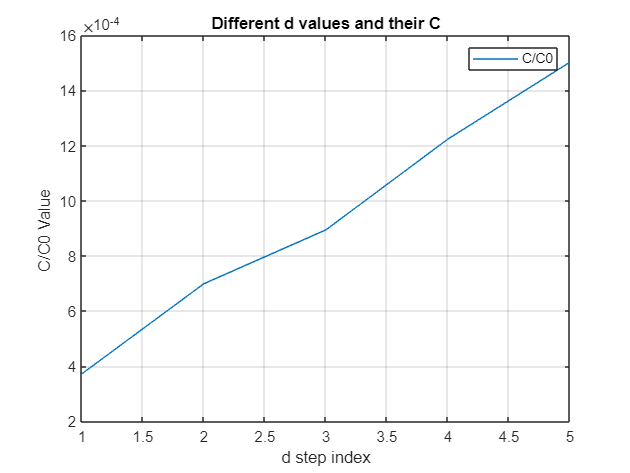



figure(2)
plot(1:length(D) , C(:,end)./C_plate)
grid on
legend("C/C0")
title("Different d values and their C")
xlabel("d step index")
ylabel("C/C0 Value ")

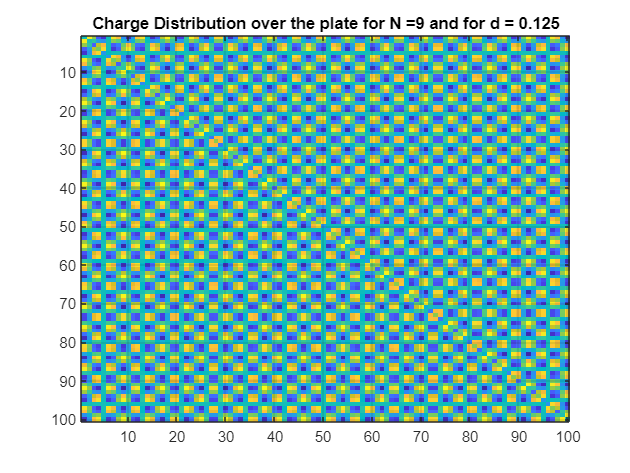



Q_T = sum( Alpha_t{1} , 'all' ) * delta_Sn; % Total Q

Charge_Distribution = Alpha_t{1};

figure(4)
imagesc(Charge_Distribution)
title("Charge Distribution over the plate for N =" + num2str(Sweep_N(1))+ " and for d = "+num2str(D(1)))
grid on

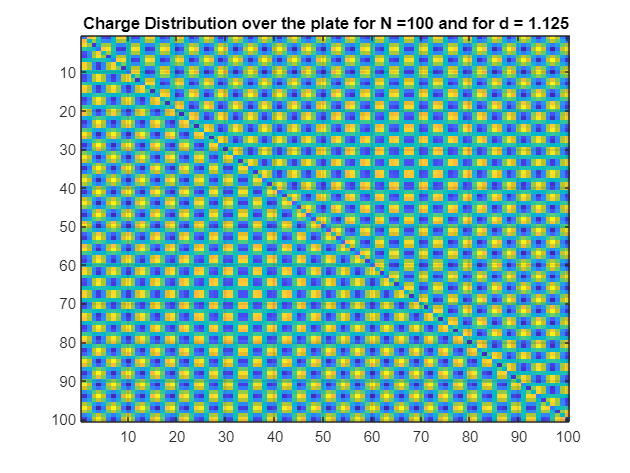

Charge_Distribution_end = Alpha_t{end};
figure(5)
imagesc(Charge_Distribution_end)
title("Charge Distribution over the plate for N =" + num2str(Sweep_N(end))+ " and for d = "+num2str(D(end)))
grid on

function lmn =  lmn_tb(a ,  N , d)
    



x = linspace(-a,a, N);
b = a/sqrt(a);
y = x;
% x_p = x;
% y_p = y;

delta_x = 1/(N+1);
delta_y = delta_x;

%Sum = 0;
eps0 = 8.854*1e-12  ;  % F/m

Lmn = zeros(N,N);

delta_Sn = (2*b)^2;
aeq  = sqrt(delta_Sn/pi)  ;

    for m=1:N
        X_int =  [x(m)-delta_x  : delta_x/10 : x(m)+delta_x ] ;
        Y_int =  [y(m)-delta_y  : delta_y/10 : y(m)+delta_y ] ;
            
            %Sum = 0;
            for n=1:N
                 X_p_int =  [x(n)-delta_x  : delta_x/10 : x(n)+delta_x ] ;
                 Y_p_int =  [x(n)-delta_x  : delta_x/10 : x(n)+delta_x ] ;
    
                    if (m ~= n )
                    Sum =  sum( 1./sqrt(   abs(X_int - X_p_int).^2 + abs(Y_int - Y_p_int).^2  + d^2  ) , 'all' )  ;
                    Sum = 1/(4*pi*eps0) * Sum;
                    Lmn(m,n) = Sum ;
                    else
                    Lmn(m,n) =  1/(2*eps0) * (sqrt(aeq^2+d^2) - d ) ;  % Approximation of the integral
                    end
            end
    end
   lmn = Lmn;
   
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



function lmn =  lmn_tt( a, N )

x = linspace(-a,a, N);
b = a/sqrt(a);
y = x;
% x_p = x;
% y_p = y;

delta_x = 1/(N+1);
delta_y = delta_x;

%Sum = 0;
eps0 = 8.854*1e-12  ;  % F/m

Lmn = zeros(N,N);

delta_Sn = (2*b)^2;

    for m=1:N
        X_int =  [x(m)-delta_x  : delta_x/10 : x(m)+delta_x ] ;
        Y_int =  [y(m)-delta_y  : delta_y/10 : y(m)+delta_y ] ;
            
            %Sum = 0;
            for n=1:N
                 X_p_int =  [x(n)-delta_x  : delta_x/10 : x(n)+delta_x ] ;
                 Y_p_int =  [x(n)-delta_x  : delta_x/10 : x(n)+delta_x ] ;
    
                    if (m ~= n )
                    Sum =  sum( 1./sqrt(   abs(X_int - X_p_int).^2 + abs(Y_int - Y_p_int).^2    ) , 'all' )  ;
                    Sum = 1/(4*pi*eps0) * Sum;
                    Lmn(m,n) = Sum ;
                    else
                    Lmn(m,n) = sqrt(delta_Sn)/eps0 * (0.2806) ;   % Approximation of the integral
                    end
            end
    end
   lmn = Lmn;
   
end

function [C , Alpha_t] = Find_C(d, N,a )

%     Lmn_tt = zeros(N,N);
%     
%     Lmn_tb = zeros(N,N);
    V =1;
    b = a / sqrt(N);
    delta_Sn  =  (2*b)^2 ;
    % eps0 = 8.854*1e-12  ;  % F/m
%     delta_X = 2*b;
%     delta_Y = 2*b;
    

    Lmn_tt  = lmn_tt( a, N );
    Lmn_tb  = lmn_tb(a ,  N , d);
        
    
    
    Alpha_t = inv(  Lmn_tt - Lmn_tb  ) * V;
    
    C = 1/(2*V) * sum(Alpha_t,'all')*delta_Sn;

end

